 one switch to run B1 (SOC), B2 (+cycle), or B3 (+calendar)

clearvars;
clc;

Choose model here 

Options: 

- 'B1' (energy only)

- 'B2' (cycle ageing)

- 'B3' (cycle+calendar)

model = 'B1';

Optional: repeat the input year R times (e.g., long-horizon)

R = 1;

Load profile 

[time, Ppv, Pload] = load_profile_bess();

time  = time(:);  Ppv = Ppv(:);  Pload = Pload(:);

if R > 1
    % repeat time & signals seamlessly
    t1 = time; dt = t1(2)-t1(1);
    per = t1(end)-t1(1)+dt;
    offsets = (0:R-1)';
    time  = repmat(t1,R,1) + repelem(offsets*per, numel(t1));
    Ppv   = repmat(Ppv,  R, 1);
    Pload = repmat(Pload,R,1);
end

Params

p = params(model);

 Run the unified core 

out = core_loop(time, Ppv, Pload, p);

Plots

- plot: PV vs Load + SOC

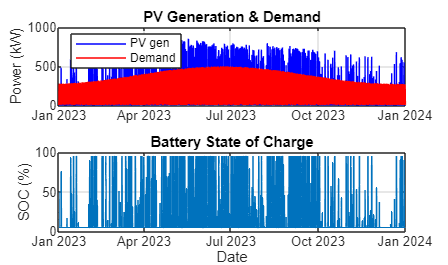

plot_bess(out.time, Ppv, Pload, out.SOC, out.SOH);

- Extra plot for B2/B3: SOH vs EFC (kept inline like your old scripts)

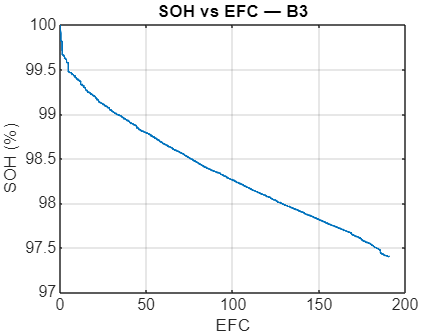

if p.modes.do_cycle
    figure('Color','w');
    plot(out.EFC, 100*out.SOH, 'LineWidth',1.1); grid on;
    xlabel('EFC'); ylabel('SOH (%)');
    title(sprintf('SOH vs EFC — %s', p.meta.model));
end

Report 

report(out);

Final SOH = 97.40%  |  EFC = 191
--- SUMMARY ---
Span: 365.0 days (1.00 years)
Cycle loss    : 0.55%
Calendar loss : 2.05%
Total loss    : 2.60%
EFC total     : 191 (0.52 per day)
